# Exercise #2 : Antenna Subsystem Analysis

clear;
clc;
format shortEng;

%---------------------------------------------------------------------------------------------------
% GOALS : 
%
% In this exercise, we will design an antenna array to replace our gaussian
% antenna placeholder. 
% 
% We will first become familiar with the sensorArrayAnalyzer App provided in Phased Array
% Toolbox to design and analyze phased arrays and will design an 8x8 array
% with isotropic radiating elements.
%
% Next, we will compare with a radiating element providing a gain > 0 dBi
% before importing the radiation pattern of a radiating element our Antenna
% Design department provided and we would like to reuse.
% 
% After we will have ran analysis, we will implement our antenna array in
% our system level simulation and will make the required modifications
% before verifying we are still able to detect our target
%
%---------------------------------------------------------------------------------------------------

## Fundamental informations

- Physical constants

c       = physconst('LightSpeed');      % speed of light
k       = physconst('Boltzmann');       % Boltzmann's constant (compute noise power density)
T       = 290.0;                        % Temperature (expressed in Kelvin)

- Center frequency is imposed by our customer and regulation

fc          = 2.4e9;     % center frequency
lambda      = freq2wavelen(fc,c);
arraySize   = [8,8];

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Use the interactive sensorArrayAnalyzer App to create an 8x8 phased array
% that will provide a "baseline" for performances comparisons.
%
%---------------------------------------------------------------------------------------------------

- **sensorArrayAnalyzer** documentation is available at :

doc sensorArrayAnalyzer

- Launch the app

sensorArrayAnalyzer

%---------------------------------------------------------------------------------------------------
%
% To design and analyze the antenna array, please follow these steps
%
%---------------------------------------------------------------------------------------------------

- Rule of thumb : proceed from left to right when using MATLAB apps :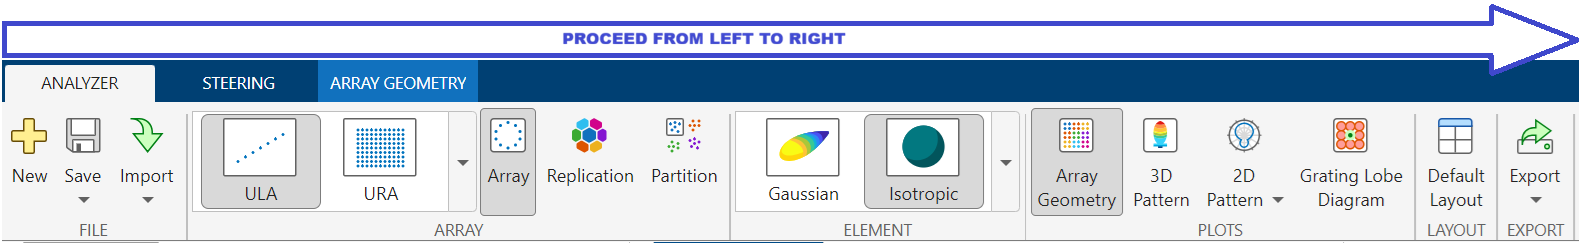

- Select URA (Uniform Rectangular Array)

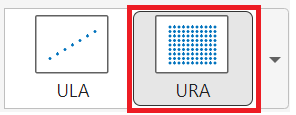

- Specify the type of radiating element (isotropic)

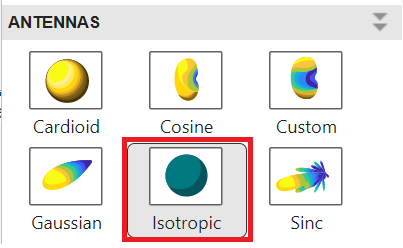

- Specify array size and element spacing (row/columns)

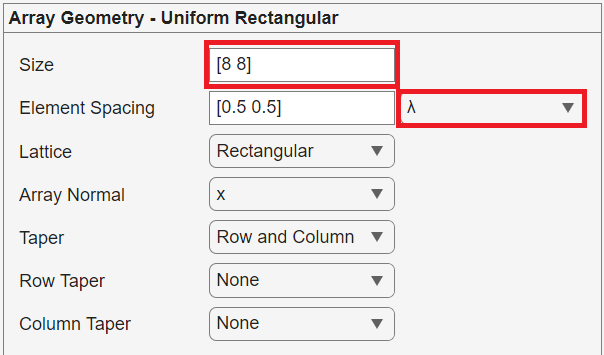

- Apply changes

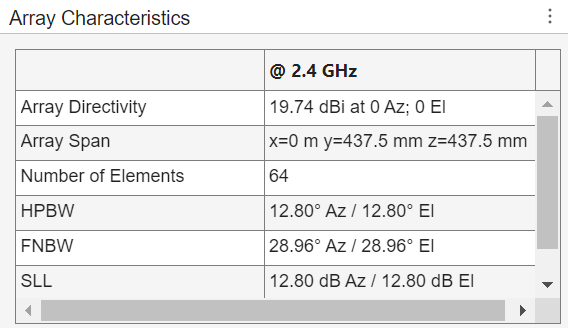

- Plot 3D Pattern

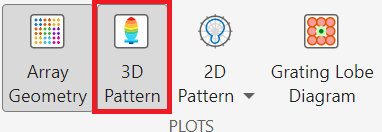

- `Option` : you also can visualize radiation pattern in 2D (azimuth and/or elevation cut)

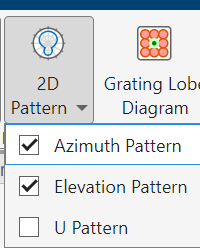

- Finally, you can export the MATLAB script :

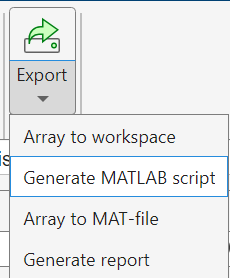

### The "baseline" : 8x8 rectangular array / Isotropic elements

- After exporting the script and minimum refactoring, the script to generate an 8x8 array looks like this :

baselineArray = phased.URA(...
    "Size", arraySize,...
    "Lattice","Rectangular",...
    "Element",phased.IsotropicAntennaElement,...
    "ElementSpacing",lambda/2,...
    "ArrayNormal","z");

- Visualize the array shape and radiation pattern using the `viewArray` and `pattern` methods

viewArray(baselineArray,"Orientation",[90;0;90])

- Visualize 3D radiation pattern

pattern(baselineArray,fc,"Type","directivity")

- Methods (Functions) will allow you to get measurements on the array you have just created

directivity(baselineArray,fc,[0;90])

- Get 2D pattern (elevation cut) and plot on a graph

patBase = patternElevation(baselineArray,fc,"Elevation",[0:180],"Type","directivity");

figure
plot (0:180,patBase)
grid on
ylim([-30, +30])
xlabel ("elevation")
ylabel('Gain (dBi)')

### Intermediate : 8x8 rectangular array / Cosine radiating element

%---------------------------------------------------------------------------------------------------
% Our Antenna R&D dept. mentionned they have designer a dual polarization antenna
% we probably could reuse. According to their simulations, the antenna
% radiating pattern should exhibit a gain of roughly 9 dBi.
% Its pattern should be close to a "cosine" antenna
%---------------------------------------------------------------------------------------------------

- We will now replace the isotropic antenna by a `cosineAntennaElement` and see how it could improve the overall gain of our antenna array...

%---------------------------------------------------------------------------------------------------
% EXERCISE
% Hint: use the 'phased.CosineAntennaElement'
% Type 'doc CosineAntennaElement' into the command line interface for more information.
%
% Create a phased.CosineAntennaElement and visualize its radiation pattern
% Call the output cosElt
%---------------------------------------------------------------------------------------------------

cosElt = phased.CosineAntennaElement("CosinePower",[1.5, 1.5]);
pattern(cosElt,fc)
directivity(cosElt,fc,[0;0])

### Optional

% pAz = patternAzimuth(cosElt,fc) ;

% figure
% plot (pAz)
% grid on
% ylim([-10,20])

%---------------------------------------------------------------------------------------------------
% The process is exactly the same as above and we simply replace the
% radiating element...
%---------------------------------------------------------------------------------------------------

intermediateArray = phased.URA(...
    "Size", arraySize,...
    "Lattice","Rectangular",...
    "Element",cosElt,...
    "ElementSpacing",lambda/2,...
    "ArrayNormal","z");

%---------------------------------------------------------------------------------------------------
% QUESTIONS
%
% Visualize the radiation pattern using the pattern method
% What is the overall gain of the antenna array (Hint : use the directivity method)
% What is the main difference with the radiation pattern measured on the
% baselineArray ?
% Discuss the results
%---------------------------------------------------------------------------------------------------

- 3D radiation pattern

pattern(intermediateArray,fc,"Type","directivity")
directivity(intermediateArray,fc,[0;90])

`Discussion : `

- While the individual radiating element exhibit a 9 dBi gain, the overall gain improvement of the URA is 'only' 3 to 4 dB...

- We will also notice the pattern is not symmetric anymore (cosine element doesn't radiate backward)

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Compare the radiation patterns in elevation (2D) of the 2x arrays (baselineArray and
% intermediateArray we have just created 
%
% Hint: you may want to use the patternElevation method
% 
% Discuss the results
% Could also test different values for "CosinePower" exponent
%---------------------------------------------------------------------------------------------------

patInt = patternElevation(intermediateArray,fc,"Elevation",[0:180],"Type","directivity");

figure
plot (0:180,patInt)
grid on
ylim([-30, +50])
hold on
plot (0:180,patBase,'r:.')
grid on
ylim([-30, +30])
hold off

`Discussion : `

- Overall gain at boresight

- Sidelobes

### Advanced : Using custom element created using antenna toolbox (EM solver)

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Our antenna R&D provided the design they have created for a dual
% polarization antenna.
%
% We will explore this design using the pcbAntennaDesignerApp and will use
% its radiation pattern,obtained through full-wave simulation in our 8x8
% array for a greated fidelity model
%
%---------------------------------------------------------------------------------------------------

- use pcbAntennaDesigner to analyze the proposed design : 

pcbAntennaDesigner

- open session / Load "`PCB_AntennaDesign.mat`"

- Explore the design (layers/feed)

- Validate the design

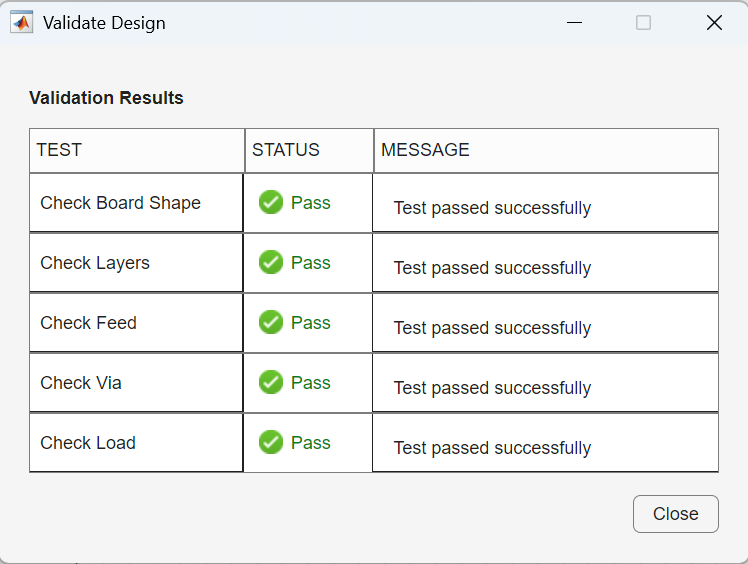

- Illustrate the ability to export MyPCB from the app

### Import the antenna design in our 8x8 URA

`Note : ``these steps will use the full-wave EM solver and will require a significant longer processing time !`

load dualPolarizedAntennaDesign.mat;

% Adjust Meshing for better representation (fine mesh = more processing
% time...)
meshconfig(dualPolarizedAntenna,'manual');

figure
mesh(dualPolarizedAntenna,"MaxEdgeLength",0.006, "MinEdgeLength",0.004, "GrowthRate",0.7)

%---------------------------------------------------------------------------------------------------
% EXERCISE
% 
% Visualize radiation pattern of the custom antenna.
% While the function name is the same (pattern), this one belongs to
% dualPolarizedAntenna (pcbStack) and will solve Maxwell's equation on the
% 3D mesh...
%
%---------------------------------------------------------------------------------------------------

- For faster analysis, we will compute one sample every 3 degrees

az = -180:3:180;
el = -90:3:90;

% Plot radiating diagram for a single element
% This step could take up to 2-3 minutes...please be patient
tic;
figure;
pattern(dualPolarizedAntenna,fc,az,el);
toc

%---------------------------------------------------------------------------------------------------
% NOTE : we now import the dualPolarizedAntenna object (pcbStack) in our
% URA
% + Cross-product integration (Antenna toolbox + Phased Array Toolbox)
% enables multi-disciplinary teams to collaborate efficiently and increase
% the level of fidelity of your simulation as elements becomes available
%
%---------------------------------------------------------------------------------------------------

- Import radiating element in the array

AESA = phased.URA(...
    "Element",dualPolarizedAntenna,...
    "Size",arraySize,...
    "ElementSpacing",lambda/2, ...
    "Lattice","Rectangular","ArrayNormal","z");

figure;
pattern(AESA,fc,az,el,"ShowArray",true)

dvty =  directivity(AESA,fc,[0;90])

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% Compare the radiation patterns in elevation (2D) of the AESA and
% baselineArray
%
% Discuss the results
%
%---------------------------------------------------------------------------------------------------

pat2 = patternElevation(AESA,fc,"Elevation",[0:180]);

figure
plot (0:180,pat2)
grid on
ylim([-30, +30])
hold on
plot (0:180,patBase)
grid on
ylim([-30, +30])

### Integrate in our model

- We first need to run the pattern method again

antennaPattern = pattern(dualPolarizedAntenna,fc,'Type','directivity');

`! A word of caution ! `

- By default, antenna toolbox will return one sample every 5 degrees

- Need to be accounted for when importing the pattern in Simulink !

- In our previous call to the function, we specified az and el angles : pattern(dualPolarizedAntenna,fc,az,el);

size(antennaPattern)

### Optional

- We could also estimate S-parameters using the Full-wave analysis :

%% Get S-Parameters
% sParametersAntenna = sparameters(dualPolarizedAntenna,fc);

- We will now integrate this pattern in our model

open_system("Ex3_Antenna_Array_Integration.slx")

%---------------------------------------------------------------------------------------------------
% EXERCISE
%
% A few things to notice...
% We now have 64x elements to feed 
%
%---------------------------------------------------------------------------------------------------

- Generate a CW signal and scale to the proper output power :

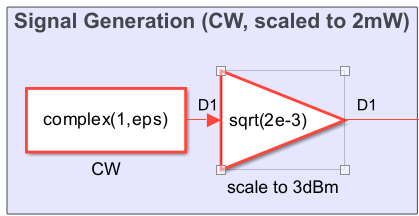

$P=\frac{V^2 }{Z_0 }$ typically, impedance is normalized to Z = 1Ohm so that : 


$$V=\sqrt{Z_0 P}$$



$$V=\sqrt{2e^{-3} }=44{\ldotp 72 e}^{-3}$$


You can check the value is as expected using a display block : 

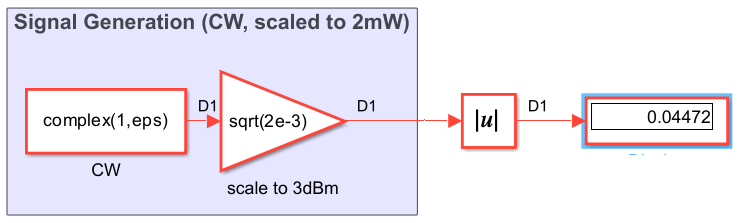

- Repeat the input signal so that it's now a 1x64 vector:

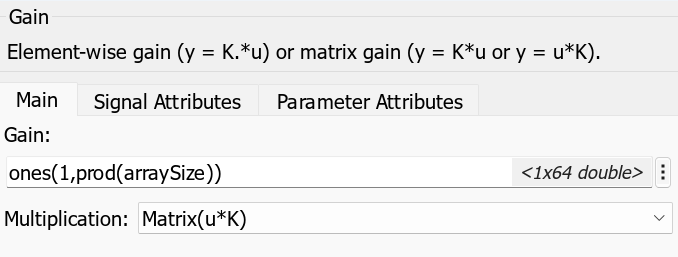

- Configure the antenna array to use the antennaPattern

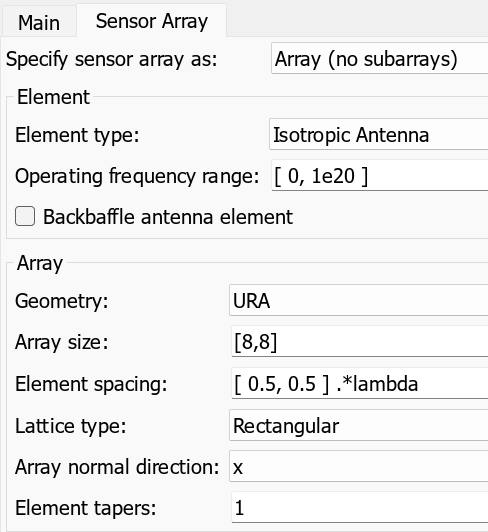

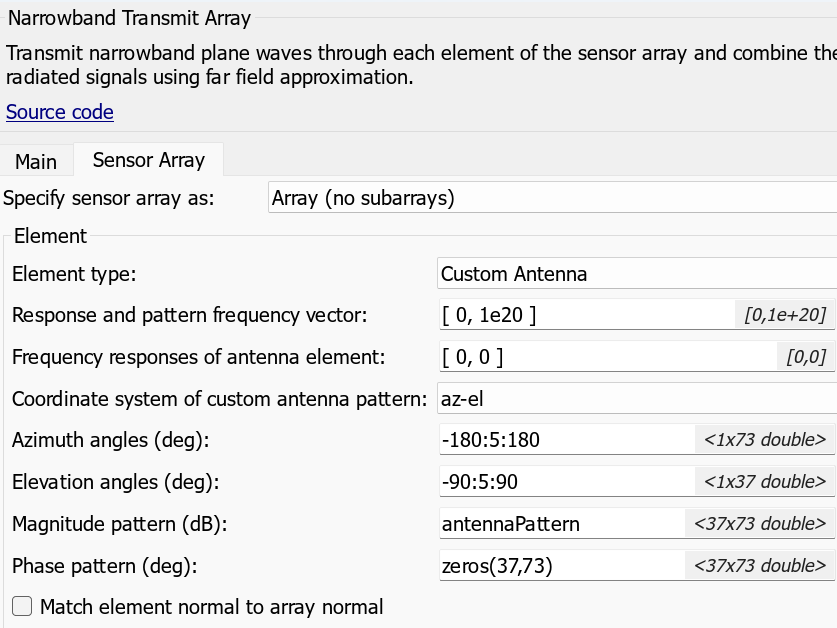

- Press the "Analyze" button

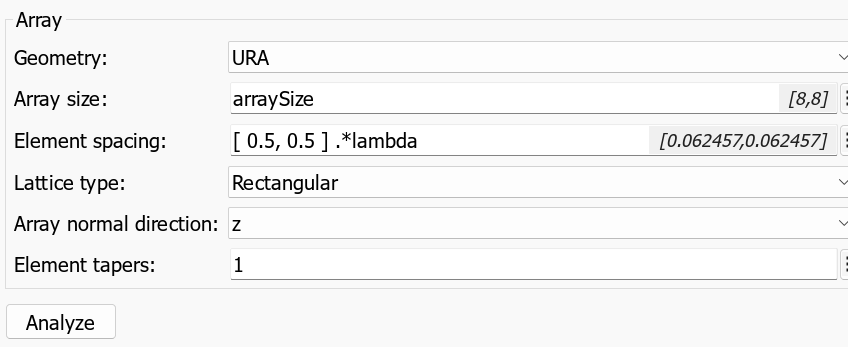

- Measure the gain at boresight (ie 90° elevation) using the interactive app

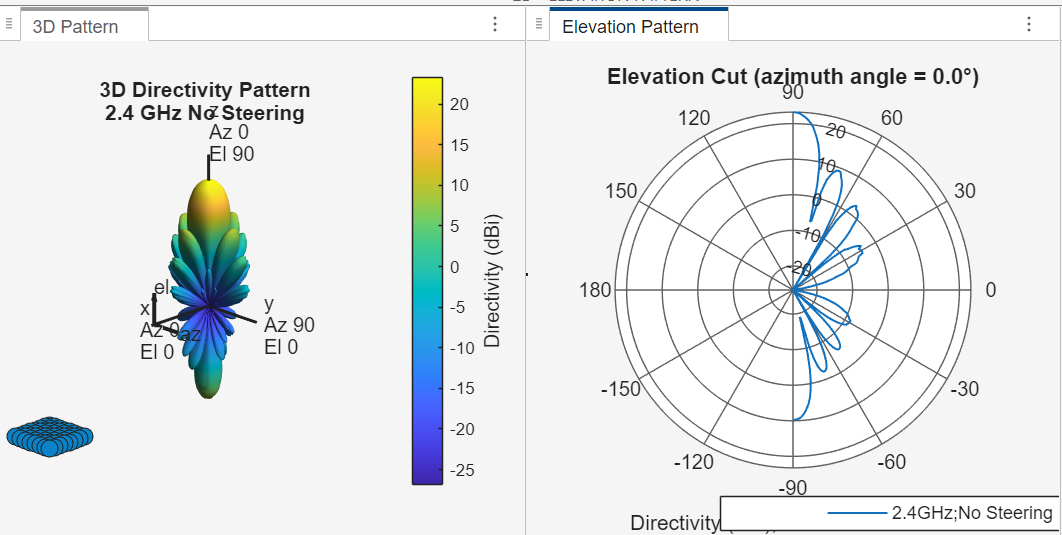

- Run the model and verify the antenna gain is as expected

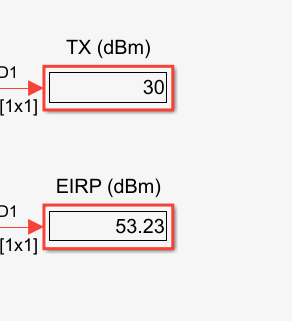

### A few tricks and experiments...

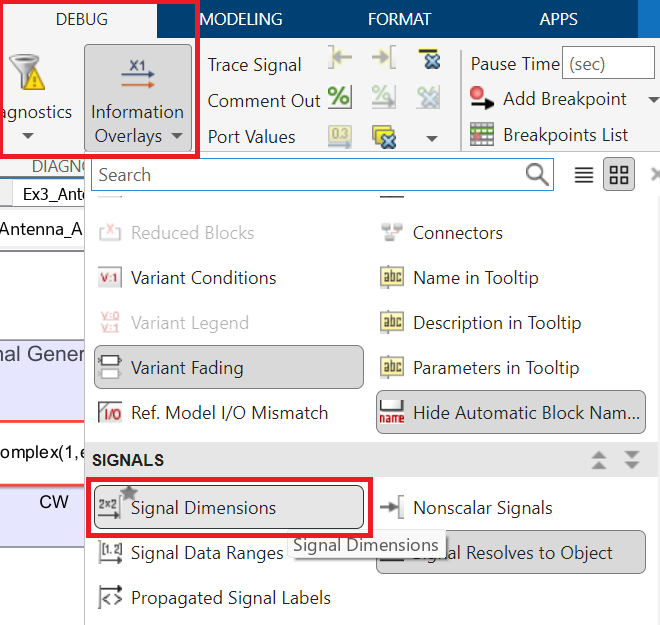

- see what happens when steering the antenna in different directions, especially where the is a Null in the sidelobe !